clear;
close all;

vehicle_type        = 0;  % 0: simquad, 1: solo, 2: simrover, 3: erle rover
is_filter_accel     = 0;

if vehicle_type == 0
    filename = 'Data/Drone/Test3/00000683.csv';
    reference_motor     = 0.3; % marks when the drone takes off
    max_freq            = 400; % sampling frequency
elseif vehicle_type == 1
    filename = 'Data/Drone/Test5/267.csv';
    reference_motor     = 0.3;
    max_freq            = 95;
elseif vehicle_type == 2 || vehicle_type == 3
    filename = 'Data/Rover/Test6/00000178.csv';
    reference_motor     = 0.04;
    max_freq            = 50;
end



test_data = csvread(filename, 2, 0);  
test_data = ClipData(vehicle_type, test_data, reference_motor, 0, 10, max_freq);

t_s         = test_data(:, 1) * 1e-6;
gyro_raw    = test_data(:, 11:13);
accel_raw   = test_data(:, 18:20);


if vehicle_type == 2 || vehicle_type ==3
    gyro_raw(:, 1:2) = 0;
end


% Filter raw accel
if is_filter_accel == 1
    fc = 1; % cut freq
    fs = max_freq; % sample freq
    [b,a] = butter(1,fc/(fs/2));
    accel_raw_filtered = filter(b,a,accel_raw);
    title_name = {'Accel x', 'Accel y', 'Accel z'};
    legend_name = {'Raw', 'Filtered', 'Error'};
    plotCompareMat(t_s, accel_raw, accel_raw_filtered, title_name, legend_name, 0);
    accel_raw = accel_raw_filtered;
end



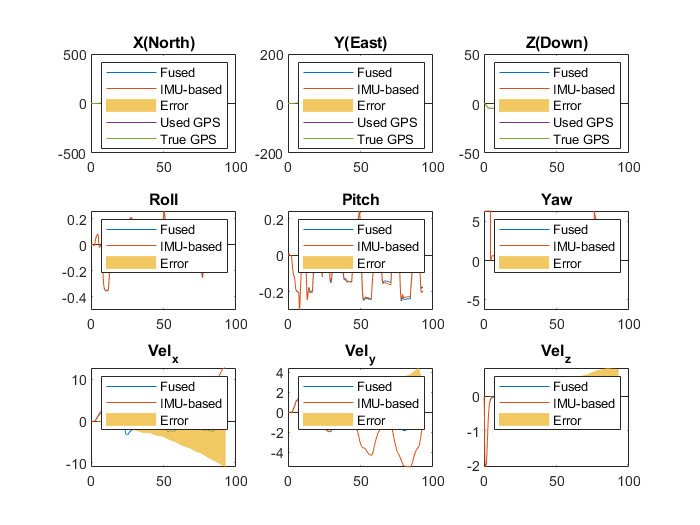

% Calculate step by step with possible synchronization

fused_states    = test_data(:, 2:10);
sync_K          = 0 * max_freq;         % unit: samples, 
start_time      = 2;                    % unit: seconds

IMU_states =  getPosFromIMU(t_s, accel_raw, gyro_raw, fused_states, sync_K, start_time);
IMU_states_mat = [IMU_states.position, IMU_states.attitude, IMU_states.velocity];

title_name = {'X(North)', 'Y(East)', 'Z(Down)', 'Roll', 'Pitch', 'Yaw', 'Vel_x', 'Vel_y', 'Vel_z'};
legend_name = {'Fused', 'IMU-based', 'Error'};
plotCompareMat(t_s, fused_states, IMU_states_mat, title_name, legend_name, 0);

if size(test_data,2) >=26
    gps_data = test_data(:, 21:26);
    for i=1:3
        hold on;
        subplot(3, 3, i);
        plot(t_s, gps_data(:, i));
        plot(t_s, gps_data(:, i+3));
        legend({'Fused', 'IMU-based', 'Error', 'Used GPS', 'True GPS'});
    end
end

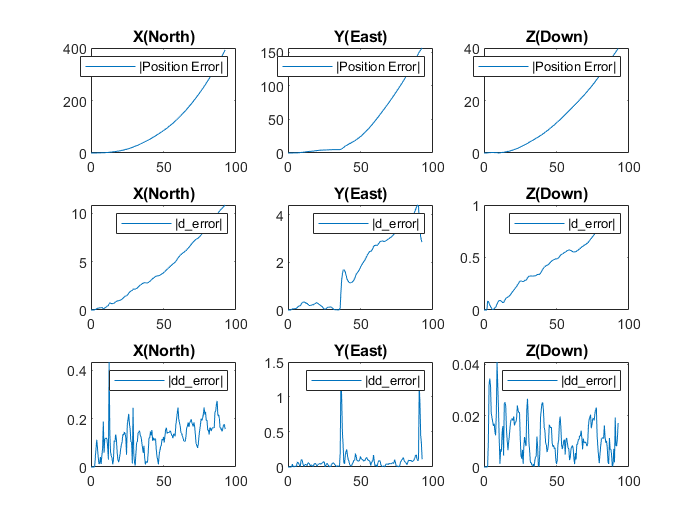

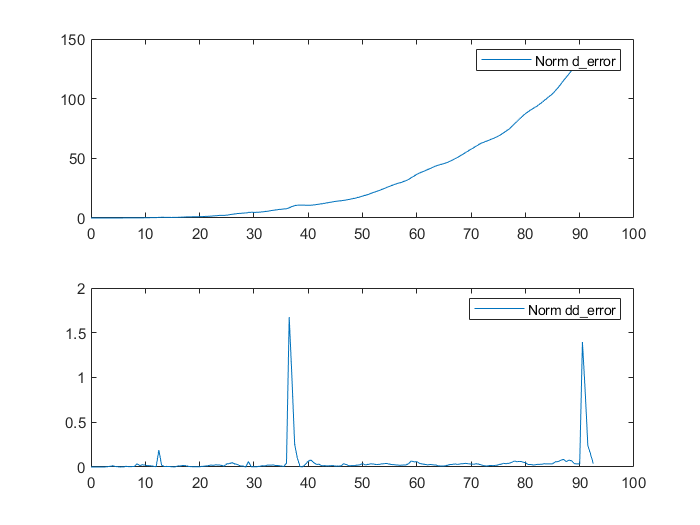

% Check spoofing

log_freq = 2;
fused_pos = test_data(:, 2:4);
d_errors = checkGPSspoofing(max_freq, log_freq, IMU_states, fused_pos);

function [t_out, d_out, idx_out] = uniqueDerivative(data, t_s, idx)
    if isempty(idx)
        [data_unique, idx_out, ~] = unique(data, 'rows', 'stable');
    else
        idx_out = idx;
        data_unique = data(idx_out, :);
    end
    
    t_out = t_s(idx_out);
    d_out = zeros(size(data_unique));
    d_out(2:end, :) = diff(data_unique)./diff(t_out);
end

function euler_angle = getEulerFromGyro(gyro, time)
euler_angle = zeros(size(gyro, 1), 3);
dt = diff(time);
for i = 1:(size(gyro,1)-1)
    phi = euler_angle(i,1);
    theta = euler_angle(i,2);
    psi = euler_angle(i, 3);
    trans_mat = [1, sin(phi)*tan(theta), cos(phi)*tan(theta);
        0, cos(phi), -sin(phi);
        0, sin(phi)/cos(theta), cos(phi)/cos(theta)];
    d_euler = (trans_mat * gyro(i, :)')';
    euler_angle(i+1, :) = euler_angle(i, :) + d_euler * dt(i);
end
euler_angle(:, 3) = wrapTo2Pi(euler_angle(:, 3));
end

function [d_errors] = checkGPSspoofing(max_freq, log_freq, IMU_states, fused_pos)
    log_skip = ceil(max_freq / log_freq);
    log_idxes = unique(sort([1:log_skip:size(IMU_states.t_s,1), find(IMU_states.sync_bits==1)']));
    t_log = IMU_states.t_s(log_idxes, :);
    
    [d_err, pos_err, dd_err] = checkErrorIncreRate(...
        t_log,...
        IMU_states.position(log_idxes, :), ...
        fused_pos(log_idxes, :),...
        IMU_states.sync_bits(log_idxes, :)...
        );
    
    
    figure;
    title_name = {'X(North)', 'Y(East)', 'Z(Down)'};
    for i = 1:3
        subplot(3, 3, i);
        plot(t_log, abs(pos_err(:, i)));
        legend({'|Position Error|'});
        title(title_name(i));
        subplot(3,3, i+3);
        plot(t_log, abs(d_err(:, i)));
        legend({'|d\_error|'});
        title(title_name(i));
        subplot(3,3,i+6);
        plot(t_log, abs(dd_err(:, i)));
        legend({'|dd\_error|'});
        title(title_name(i));
    end
    
    figure;
    subplot(2,1,1)
    norm_error_rate = sum(abs(d_err) .* abs(d_err), 2);
    plot(t_log, norm_error_rate);
    legend('Norm d\_error')
    subplot(2,1,2)
    norm_dd_err = sum(abs(dd_err) .* abs(dd_err), 2);
    plot(t_log, norm_dd_err)
    legend('Norm dd\_error')

    d_errors.d_err = d_err;
    d_errors.dd_err = dd_err;
    d_errors.t_log = t_log;
    d_errors.norm_d_err = norm_error_rate;
    d_errors.norm_dd_err = norm_dd_err;
end

function data_ef = transBf2Ef(data_bf, euler_angle)
    rotm = eul2rotm(euler_angle(:, [3,2,1]), 'ZYX');
    data_ef = zeros(size(data_bf, 1),3);
    for i = 1:size(data_bf,1)
        data_ef(i, :) = (rotm(:,:,i) * data_bf(i, :)')';
    end
end

function plotCompareMat(x_axis, A_data, B_data, title_name, legend_name, is_wrapPi)
    figure;
    N = size(A_data,2);
    for i=1:N
        subplot(ceil(N/3),3,i);
        plot(x_axis, A_data(:, i));
        hold on;
        plot(x_axis, B_data(:, i));
        hold on;
        if is_wrapPi
            error = wrapToPi(A_data(:, i) - B_data(:, i));
        else
            error = A_data(:, i) - B_data(:, i);
        end
%         yyaxis right
        area(x_axis, error , 'FaceAlpha', 0.7, 'EdgeColor','none');
        legend(legend_name);
        title(title_name(i));
    end
end

function [d_err, pos_err, dd_err] = checkErrorIncreRate(t, position, pos_gt, sync_bits)
    % position and pos_gt are N by 3 mat
    % sync_bits is N by 1 binary bits
    pos_err = (pos_gt - position);
    d_err = [0,0,0; diff(pos_err) ./ diff(t)];
    d_err(logical(sync_bits), :) = 0; % ignore d_error of sync data
    
    next_sync_bits = circshift(sync_bits,1);
    d_err(logical(next_sync_bits), :) = 0; % ignore d_error of sync data to next log
    
    dd_err = [0,0,0; diff(d_err) ./ diff(t)];
    dd_err(logical(sync_bits), :) = 0; % ignore dd_error of sync data
    
    next_next_sync_bits = circshift(sync_bits,2);
    dd_err(logical(next_next_sync_bits), :) = 0; % ignore dd_error of zeroed data to next log
    
end


function [position, velocity] =  getPosFromAccel(time, accel, pos_gt, vel_gt, start_time)
    start_idx = find(time >= start_time, 1);
    position = zeros(size(pos_gt, 1), 3);
    velocity = zeros(size(vel_gt, 1), 3);
    position(1:start_idx, :) = pos_gt(1:start_idx, :);
    velocity(1:start_idx, :) = vel_gt(1:start_idx, :);
    
    accel_cut = accel(start_idx:end, :);
    time_cut = time(start_idx:end, :);
    
    delta_v = accel_cut(1:end-1, :) .* diff(time_cut);
    delta_v_cum = cumsum(delta_v);
    velocity(start_idx+1:end, :) = vel_gt(start_idx, :) + delta_v_cum;
    vel_cut = velocity(start_idx:end, :);
    delta_pos = vel_cut(1:end-1, :) .* diff(time_cut);
    delta_pos_cum = cumsum(delta_pos);
    position(start_idx+1:end, :) = pos_gt(start_idx, :) + delta_pos_cum;
end

function [IMU_states] =  getPosFromIMU(t_s, accel_raw, gyro_raw, states_gt, sync_K, start_time)
    x_gt = states_gt';
    
    gyro_bf = gyro_raw';
    accel_bf = accel_raw';
    x = zeros(size(x_gt));
    N = size(x, 2);
    sync_bits = zeros(N, 1);
    x(:, 1) = x_gt(:, 1);
    sync_bits(1) = 1;
    for i = 2:N
        dt = t_s(i) - t_s(i-1);
        dx = states_odefun(x(:, i-1), accel_bf(:, i-1), gyro_bf(:, i-1));
        x(:, i) = x(:, i-1) + dx * dt;
        x(6, i) = wrapTo2Pi(x(6, i));
        
        % sync for before start_time
        if i * dt < start_time
            sync_bits(i) = 1;
            x(:, i) = x_gt(:, i);
        end
        
        % K-step sync
        if sync_K > 0 && mod(i, sync_K) == 0
            sync_bits(i) = 1;
            x(:, i) = x_gt(:, i);
%             x(1:6, i) = x_gt(1:6, i); % only sync position and attitude
        end
    end
    IMU_states.position = x(1:3, :)';
    IMU_states.attitude = x(4:6, :)';
    IMU_states.velocity = x(7:9, :)';
    IMU_states.sync_bits = sync_bits;
    IMU_states.t_s = t_s;
end


function dx = states_odefun(x, accel_bf, gyro_bf)
% all input are column vectors
%  x: 1:3 postion,  4:6 euler angles,       7:9 velocity
% dx: 1:3 velocity, 4:6 euler angles rate,  7:9 acceleration
    g = 9.80665;
    dx = zeros(size(x));
    dx(1) = x(7);
    dx(2) = x(8);
    dx(3) = x(9);
        phi = x(4);
        theta = x(5);
        psi = x(6);
        trans_mat = [1, sin(phi)*tan(theta), cos(phi)*tan(theta);
            0, cos(phi), -sin(phi);
            0, sin(phi)/cos(theta), cos(phi)/cos(theta)];
    dx(4:6) = trans_mat * gyro_bf;
    dx(7:9) = eul2rotm(x([6,5,4])', 'ZYX') * accel_bf + [0, 0, g]';
    
end